# **Exercise 9**

clear

% 1. setup

    % demograhpics
    par.T     = 10;
    
    % preferences 
    par.rho   = 2.0;
    par.beta  = 0.98;
    par.u     = @(x,par) x.^(1.0-par.rho)/(1.0-par.rho);
    
    % income and interest rate
    par.R        = 1.0/par.beta;
    par.sigma_xi = 0.2;
    
    % optimizer settings
    par.options = optimoptions('fsolve',...
                        'Display','none',...
                        'Algorithm','Levenberg-Marquardt',...
                        'StepTolerance',1e-6,...
                        'FunctionTolerance',1e-6,...
                        'MaxIterations',500);

% 2. states
par.NM    = 100;
par.M_max = 5;

% 3. Gauss-Hermite
par.N_GH = 8;
[x, w]   = GaussHermite(par.N_GH);
par.Y    = exp(x*sqrt(2)*par.sigma_xi);
par.w    = w./sqrt(pi);
    
% 4. solve
[Cstar, par] = ti_finite(par);

Reference to non-existent field 'G_M'.

Error in ti_finite>find_Cstar (line 31)
    for i_M = 1:numel(par.G_M)

Error in ti_finite (line 21)
        Cstar{t} = find_Cstar(par);             

## Figures

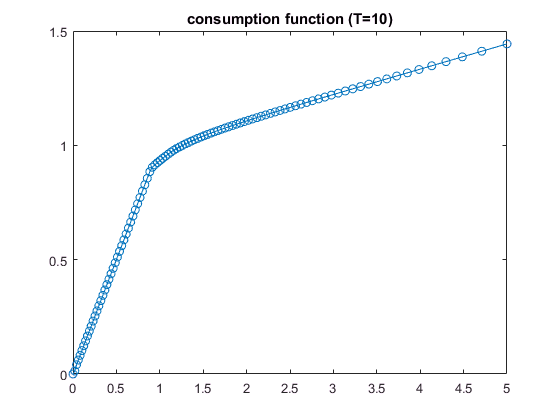

figure ();
plot(par.grid_M,Cstar{1},'-o')
title('consumption function (T=10)')

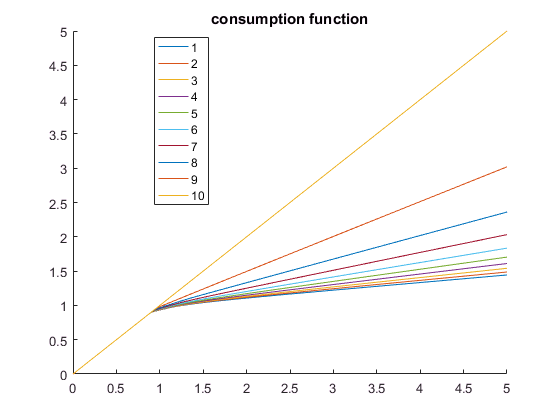


figure();
hold('on');
for t = 1:1:par.T
    plot(par.grid_M,Cstar{t},'-','DisplayName',sprintf('%d',t))    
end
title('consumption function')
legend('Location','best')

## Simulate

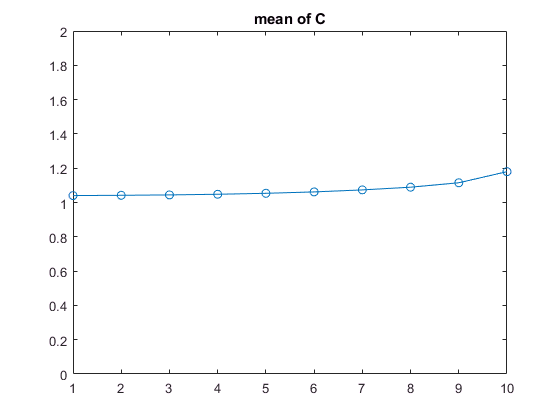

par.simN = 100000;
M_ini    = 1.5;

% 1. allocate
simM = M_ini*ones(par.simN,par.T);
simC = ones(par.simN,par.T);

% 2. simulate
rng(2017)
for t = 1:par.T
    Cstar_interp = griddedInterpolant(par.grid_M,Cstar{t},'linear');
    simC(:,t)    = Cstar_interp(simM(:,t)); 
    if t < par.T
        A = simM(:,t)-simC(:,t);
        Y = exp(randn(par.simN,1)*par.sigma_xi);
        simM(:,t+1) =  par.R*A + Y;
    end
end

% 3. figure
figure
plot(1:par.T,mean(simC),'-o')
ylim([0,2])
title('mean of C')

## Euler-errors

% 1. interpolants
Cstar_interp      = griddedInterpolant(par.grid_M,Cstar{1},'linear');
Cstar_plus_interp = griddedInterpolant(par.grid_M,Cstar{2},'linear');

% 2. consumption today and tomorrow
M_ini  = 1.5;
C      = Cstar_interp(M_ini);
A      = M_ini - C;
C_plus = Cstar_plus_interp(par.R*A+par.Y);

% 3. euler errors
euler_error      = abs(marg_u(C,par) - par.beta*par.R*sum(par.w.*marg_u(C_plus,par)));
norm_euler_error = log10(euler_error/C);

% 4. mean and print
I = A > 0.01;
fprintf('eule_error = %6.4f, normalized_euler_error %6.4f\n',euler_error(I),norm_euler_error(I))

eule_error = 0.0001, normalized_euler_error -4.2545


## LOCAL FUNCTIONS

function [y] = marg_u(C,par)
    y = C.^(-par.rho);
end
